% Метод случайного баланса - ранжирование факторов

clear
global m n a

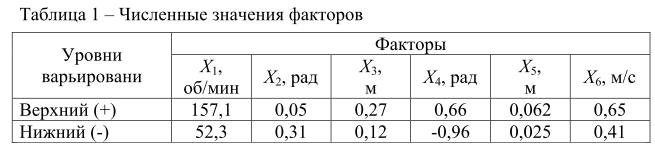

X=[157.1 0.05 0.27 0.66 0.062 0.65;
    52.3 0.31 0.12 -0.96 0.025 0.41];

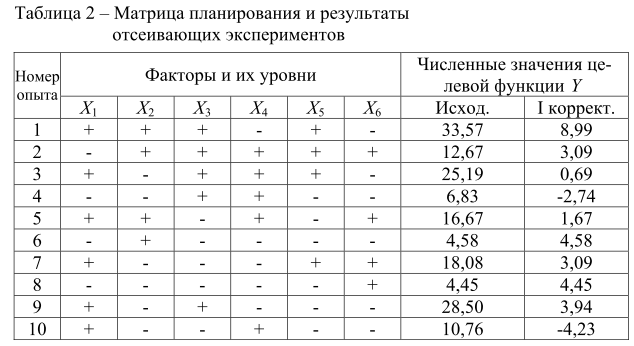

B=[1  1  1 -1  1 -1;
  -1  1  1  1  1  1;
   1 -1  1  1  1 -1;
  -1 -1  1  1 -1 -1;
   1  1 -1  1 -1  1;
  -1  1 -1 -1 -1 -1;
   1 -1 -1 -1  1  1;
  -1 -1 -1 -1 -1  1;
   1 -1  1 -1 -1 -1;
   1 -1 -1  1 -1 -1];

a=0.95; % уровень доверительной вероятности
m=length(B(:,1)); %количество строк В
n=length(B(1,:)); %количество столбцов В

% Определение численных значений целевой функции Y и вывод их на экран

for i=1:m
    for j=1:n
        switch B(i, j)
            case 1
                M(i,j)=X(1,j);
            case -1
                M(i,j)=X(2,j);
        end
    end
end

for i=1:length(M(:, 1))
    X=M(i, :);
    Y(i, 1)=(X(1)*(X(5)*cos(X(2))+X(3)*cos(X(2)+X(4)))*X(3)*X(1)*cos(X(2)+X(4))+ ...
        X(6)*(1-sin(X(2))))/(X(1)*X(3)*(1+sin(X(2)))*cos(X(2)+X(4))+X(6)*(cos(X(2)))^2);
end

[B Y]

ans =     1.0000    1.0000    1.0000   -1.0000    1.0000   -1.0000   33.5710
   -1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   12.6112
    1.0000   -1.0000    1.0000    1.0000    1.0000   -1.0000   25.1908
   -1.0000   -1.0000    1.0000    1.0000   -1.0000   -1.0000    6.8535
    1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   16.6730
   -1.0000    1.0000   -1.0000   -1.0000   -1.0000   -1.0000    4.5486
    1.0000   -1.0000   -1.0000   -1.0000    1.0000    1.0000   18.0861
   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000    1.0000    4.4495
    1.0000   -1.0000    1.0000   -1.0000   -1.0000   -1.0000   28.5062
    1.0000   -1.0000   -1.0000    1.0000   -1.0000   -1.0000   10.7646


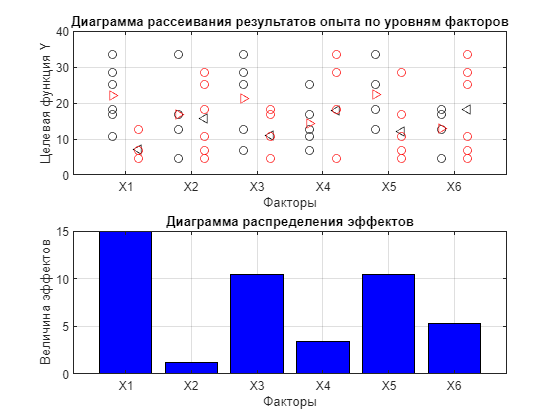


%Расчет медианы каждого фактора

figure
for j=1:n
    A1=[]; A2=[];
    for i=1:m
        if B(i, j)==1
            A1(end+1)=Y(i);
            
        else
            A2(end+1)=Y(i);
        end
    end
    A(j)=abs(mean(A1)-mean(A2)); %вычисление медианы каждого j фактора

    subplot(2,1,1) 
    plot(j-0.2, A1, 'ok', j-0.2, mean(A1), '>r', j+0.2, mean(A2), '<k', j+0.2, A2, 'or');
    %MarkerSize=15; %Размер узлов-маркеров
    xtickformat('X%,.0f')
    hold on;   grid on;
        
    subplot(2,1,2) 
    bar(j, A(j), 'b' )
    set(gca,'XTickMode','Auto')
    xtickformat('X%,.0f')
    hold on;  grid on;
end

subplot(2,1,1)
title('Диаграмма рассеивания результатов опыта по уровням факторов') 
xlabel('Факторы')
ylabel('Целевая функция Y')
xlim([0.2 n+0.8])

subplot(2,1,2)
title('Диаграмма распределения эффектов') 
xlabel('Факторы')
ylabel('Величина эффектов')
xlim([0.2 n+0.8])

hold off

% Выделение двух факторов наибольших по влиянию (по медиане)
[~, idx]=sort(A,'descend')

idx =      1     3     5     6     4     2




Tab1=[]; Tab2=[]; Tab3=[]; Tab4=[];

for i=1:m
    if B(i, idx(1))==1 && B(i, idx(2))==1
        Tab1(end+1)=Y(i);
    elseif B(i, idx(1))==-1 && B(i, idx(2))==1
        Tab2(end+1)=Y(i);
    elseif B(i, idx(1))==1 && B(i, idx(2))==-1
        Tab3(end+1)=Y(i);
    else 
        Tab4(end+1)=Y(i);
    end
end
Tab1, Tab2, Tab3, Tab4

Tab1 =    33.5710   25.1908   28.5062


Tab2 =    12.6112    6.8535


Tab3 =    16.6730   18.0861   10.7646


Tab4 =     4.5486    4.4495


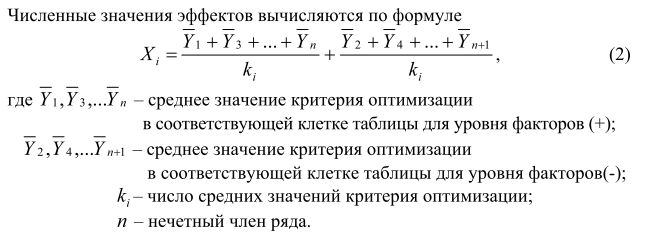

%Вычисление эффектов факторов
Eff1=(mean(Tab1)+mean(Tab3))/2-(mean(Tab2)+mean(Tab4))/2

Eff1 = 15.0163

Eff2=(mean(Tab1)+mean(Tab2))/2-(mean(Tab3)+mean(Tab4))/2

Eff2 = 9.5741


        %Проверка значимости факторов по критерию Стьюдента

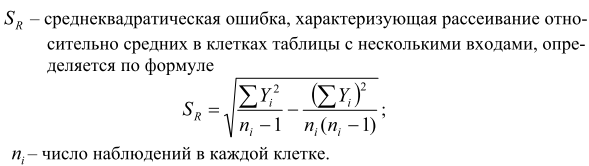

%Вычисление среднеквадратической ошибки Sr 
Tab=Tab1;
c=length(Tab); 
Sr(1, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;

Tab=Tab2;
c=length(Tab);
Sr(2, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;

Tab=Tab3;
c=length(Tab);
Sr(3, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;    

Tab=Tab4;
c=length(Tab);
Sr(4, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;

%Расчетное значение критерия Стьюдента для 1 и 2 значимого  фактора
t1=((mean(Tab1)+mean(Tab3))-(mean(Tab2)+mean(Tab4)))/sqrt(sum(Sr));
t2=((mean(Tab1)+mean(Tab2))-(mean(Tab3)+mean(Tab4)))/sqrt(sum(Sr));

%Вычисление числа степени свободы
f=length([Tab1 Tab2 Tab3 Tab4])-4; % где 4 - число клеток в таблице 3

%Tабличное значение критерия Стьюдента
ts=tinv((1+a)/2, f); 

%Вывод на экран результатов проверки значимости факторов
if abs(t1)>abs(ts) 
    fprintf('Фактор X%d значим при доверительной вероятности %.2f \n', idx(1), a)
    fprintf('т.к. tрасч=|%f|> tтеор=%f \n', t1, ts)
else
    fprintf('Фактор X%d незначим при доверительной вероятности %.2f \n', idx(1), a)
    fprintf('т.к. tрасч=|%f| < tтеор=%f \n', t1, ts)
end

Фактор X1 значим при доверительной вероятности 0.95 


т.к. tрасч=|6.844017|> tтеор=2.446912 



if abs(t2)>abs(ts)
    fprintf('Фактор X%d значим при доверительной вероятности %.2f \n', idx(2), a)
    fprintf('т.к. tрасч=|%f| > tтеор=%f \n', t2, ts)
else
    fprintf('Фактор X%d незначим при доверительной вероятности %.2f \n', idx(2), a)
    fprintf('т.к. tрасч=|%f| < tтеор=%f \n', t2, ts)
end

Фактор X3 значим при доверительной вероятности 0.95 


т.к. tрасч=|4.363603| > tтеор=2.446912 



%1 Корректировка значений целевой функции с учетом влияния эффектов факторов

for i=1:m
    if B(i, idx(1))==1 && B(i, idx(2))==1
        Yk(i)=Y(i)-Eff1-Eff2;
    elseif B(i, idx(1))==1 && B(i, idx(2))==-1
        Yk(i)=Y(i)-Eff1;
    elseif B(i, idx(1))==-1 && B(i, idx(2))==1
        Yk(i)=Y(i)-Eff2;
    else
        Yk(i)=Y(i);
    end
end

Yk=Yk'

Yk =     8.9807
    3.0371
    0.6005
   -2.7206
    1.6567
    4.5486
    3.0698
    4.4495
    3.9159
   -4.2517


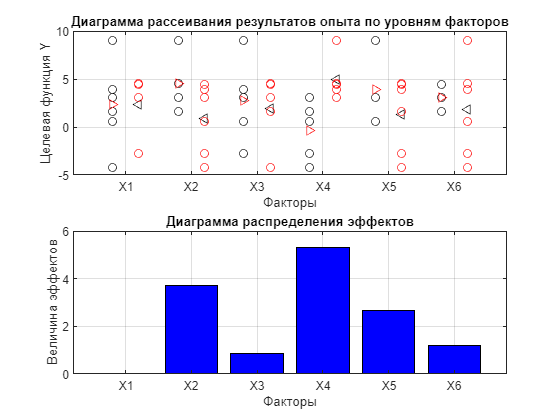

%Расчет медианы каждого фактора c учетом отброшенных первых двух значимых факторов
%Определение 3 и 4 фактора

figure
for j=1:n
    A1=[]; A2=[];
    for i=1:m
        if B(i, j)==1
            A1(end+1)=Yk(i);
            
        else
            A2(end+1)=Yk(i);
        end
    end
    A(j)=abs(mean(A1)-mean(A2)); %вычисление медианы каждого j фактора

    subplot(2,1,1) 
    plot(j-0.2, A1, 'ok', j-0.2, mean(A1), '>r', j+0.2, mean(A2), '<k', j+0.2, A2, 'or');
    %MarkerSize=15; %Размер узлов-маркеров
    xtickformat('X%,.0f')
    hold on;   grid on;
        
    subplot(2,1,2) 
    bar(j, A(j), 'b' )
    set(gca,'XTickMode','Auto')
    xtickformat('X%,.0f')
    hold on;  grid on;
   
end

subplot(2,1,1)
title('Диаграмма рассеивания результатов опыта по уровням факторов') 
xlabel('Факторы')
ylabel('Целевая функция Y')
xlim([0.2 n+0.8])

subplot(2,1,2)
title('Диаграмма распределения эффектов') 
xlabel('Факторы')
ylabel('Величина эффектов')
xlim([0.2 n+0.8])

hold off


% Выделение двух факторов наибольших по влиянию (по медиане)
[~, idx2]=sort(A,'descend')

idx2 =      4     2     5     6     3     1



Tab1=[]; Tab2=[]; Tab3=[]; Tab4=[];

for i=1:m
    if B(i, idx2(1))==1 && B(i, idx2(2))==1
        Tab1(end+1)=Yk(i);
    elseif B(i, idx2(1))==-1 && B(i, idx2(2))==1
        Tab2(end+1)=Yk(i);
    elseif B(i, idx2(1))==1 && B(i, idx2(2))==-1
        Tab3(end+1)=Yk(i);
    else 
        Tab4(end+1)=Yk(i);
    end
end
%Вычисление эффектов факторов
Effk1=(mean(Tab1)+mean(Tab3))/2-(mean(Tab2)+mean(Tab4))/2

Effk1 = -5.1767

Effk2=(mean(Tab1)+mean(Tab2))/2-(mean(Tab3)+mean(Tab4))/2

Effk2 = 3.7119


        %Проверка значимости факторов по критерию Стьюдента

%Вычисление среднеквадратической ошибки Sr 
Tab=Tab1;
c=length(Tab); 
Sr(1, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;

Tab=Tab2;
c=length(Tab);
Sr(2, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;

Tab=Tab3;
c=length(Tab);
Sr(3, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;    

Tab=Tab4;
c=length(Tab);
Sr(4, 1)=(sum(Tab.^2)/(c-1)-((sum(Tab)^2)/(c*(c-1))))/c;

%Расчетное значение критерия Стьюдента для 1 и 2 значимого  фактора
t1=((mean(Tab1)+mean(Tab3))-(mean(Tab2)+mean(Tab4)))/sqrt(sum(Sr));
t2=((mean(Tab1)+mean(Tab2))-(mean(Tab3)+mean(Tab4)))/sqrt(sum(Sr));

%Вычисление числа степени свободы
f=length([Tab1 Tab2 Tab3 Tab4])-4; % где 4 - число клеток в таблице 3

%Tабличное значение критерия Стьюдента
ts=tinv((1+a)/2, f); 

%Вывод на экран результатов проверки значимости факторов
if abs(t1)>abs(ts) 
    fprintf('Фактор X%d значим при доверительной вероятности %.2f \n', idx2(1), a)
    fprintf('т.к. tрасч=|%f|> tтеор=%f \n', t1, ts)
else
    fprintf('Фактор X%d незначим при доверительной вероятности %.2f \n', idx2(1), a)
    fprintf('т.к. tрасч=|%f| < tтеор=%f \n', t1, ts)
end

Фактор X4 значим при доверительной вероятности 0.95 


т.к. tрасч=|-3.755667|> tтеор=2.446912 



if abs(t2)>abs(ts)
    fprintf('Фактор X%d значим при доверительной вероятности %.2f \n', idx2(2), a)
    fprintf('т.к. tрасч=|%f| > tтеор=%f \n', t2, ts)
else
    fprintf('Фактор X%d незначим при доверительной вероятности %.2f \n', idx2(2), a)
    fprintf('т.к. tрасч=|%f| < tтеор=%f \n', t2, ts)
end

Фактор X2 значим при доверительной вероятности 0.95 


т.к. tрасч=|2.692955| > tтеор=2.446912 


%Вычисление эффектов 5 и 6 факторов
Tab11=[]; Tab22=[]; Tab33=[]; Tab44=[];

for i=1:m
    if B(i, idx(3))==1 && B(i, idx(4))==1
        Tab11(end+1)=Yk(i);
    elseif B(i, idx2(3))==-1 && B(i, idx2(4))==1
        Tab22(end+1)=Yk(i);
    elseif B(i, idx2(3))==1 && B(i, idx2(4))==-1
        Tab33(end+1)=Yk(i);
    else 
        Tab44(end+1)=Yk(i);
    end
end
%Вычисление эффектов факторов
Effk3=(mean(Tab11)+mean(Tab33))/2-(mean(Tab22)+mean(Tab44))/2;
Effk4=(mean(Tab11)+mean(Tab22))/2-(mean(Tab33)+mean(Tab44))/2;

b=abs([Eff1, Eff2, Effk1, Effk2, Effk3, Effk4])

b =    15.0163    9.5741    5.1767    3.7119    2.2089    0.4715


x=[idx(1), idx(2), idx2(1), idx2(2), idx2(3), idx2(4)]

x =      1     3     4     2     5     6


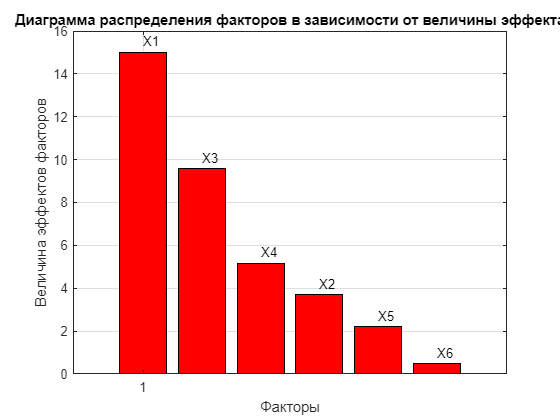


figure
for i=1:n
    str_k=['X',num2str(x(i))];
    bar(i, abs(b(i)), 'r' )
    text(i, 0.5+b(i), str_k, 'FontSize', 10)
    hold on;
    grid on;
    %set(gca,'XTickMode','Auto')
end
title('Диаграмма распределения факторов в зависимости от величины эффекта') 
xlabel('Факторы')
ylabel('Величина эффектов факторов')